## **Вариант 8**

## **Задание 1. Одноканальная система в форме вход-выход**

a2 = 9;
a1 = 26;
a0 = 24;
b2 = 2;
b1 = 6;
b0 = 8;

mdl = "task1";
open_system(mdl);

simIn = Simulink.SimulationInput(mdl);

out1 = sim(simIn);

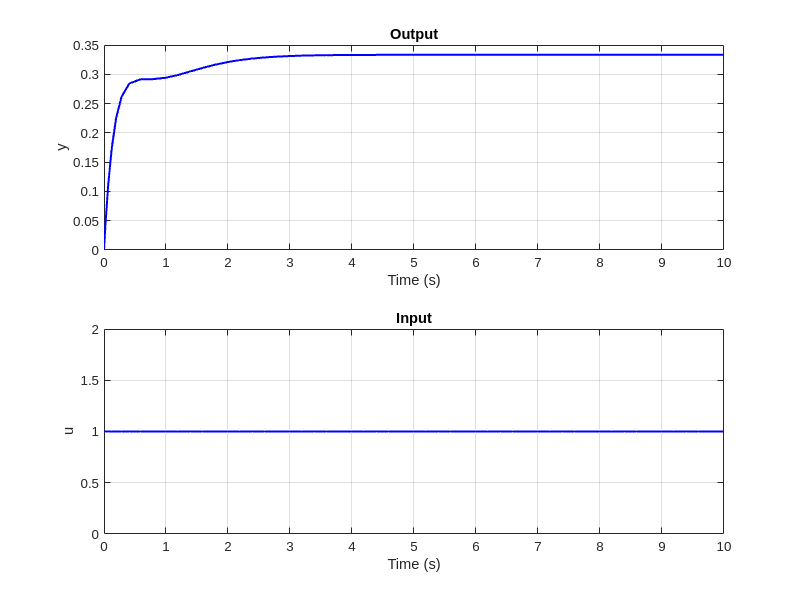

res = get(out1, "yout");
y = res{1};
u = res{2};

% Получение времени симуляции
t = out1.tout;

% Построение графика
figure('Position', [0 0 800 600]);

subplot(2, 1, 1); 
plot(t, y.Values.Data, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('y');
title('Output');
grid on;

subplot(2, 1, 2); 
plot(t, u.Values.Data, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('u');
title('Input');
grid on;

## Задание 2. Переход от формы вход-выход к форме вход-состояние-выход

mdl = "task2_ctrl";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out2 = sim(simIn);

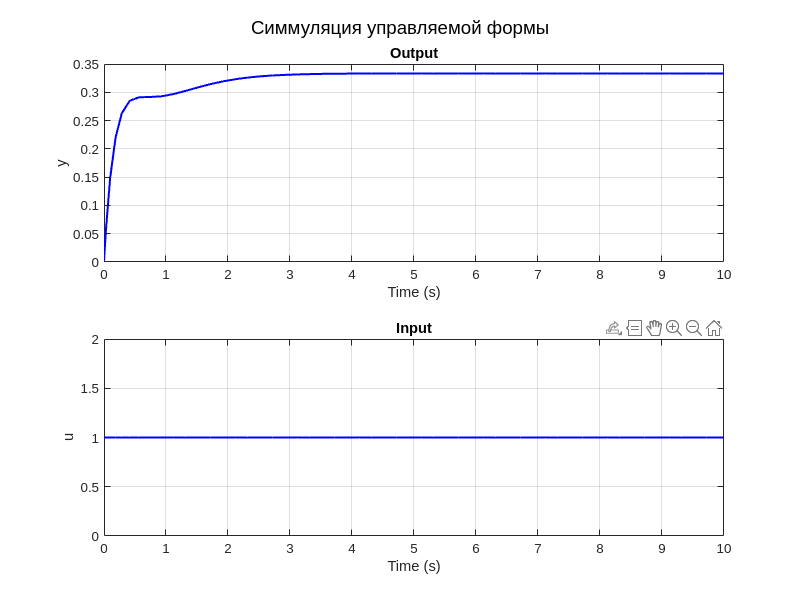

res = get(out2, "yout");
y = res{1};
u = res{2};
t = out2.tout;

figure('Position', [0 0 800 600]);

subplot(2, 1, 1); 
plot(t, y.Values.Data, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('y');
title('Output');
grid on;

subplot(2, 1, 2); 
plot(t, u.Values.Data, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('u');
title('Input');
grid on;

sgtitle("Симмуляция управляемой формы")

mdl = "task2_wtch";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out3 = sim(simIn);

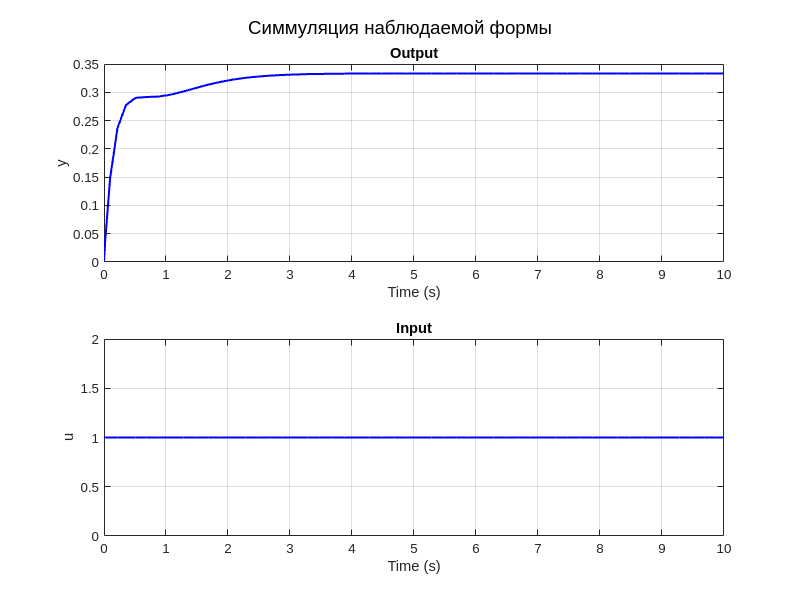

res = get(out3, "yout");
y = res{1};
u = res{2};
t = out3.tout;

figure('Position', [0 0 800 600]);

subplot(2, 1, 1); 
plot(t, y.Values.Data, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('y');
title('Output');
grid on;

subplot(2, 1, 2); 
plot(t, u.Values.Data, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('u');
title('Input');
grid on;

sgtitle("Симмуляция наблюдаемой формы")

mdl = "task2_diag";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out4 = sim(simIn);

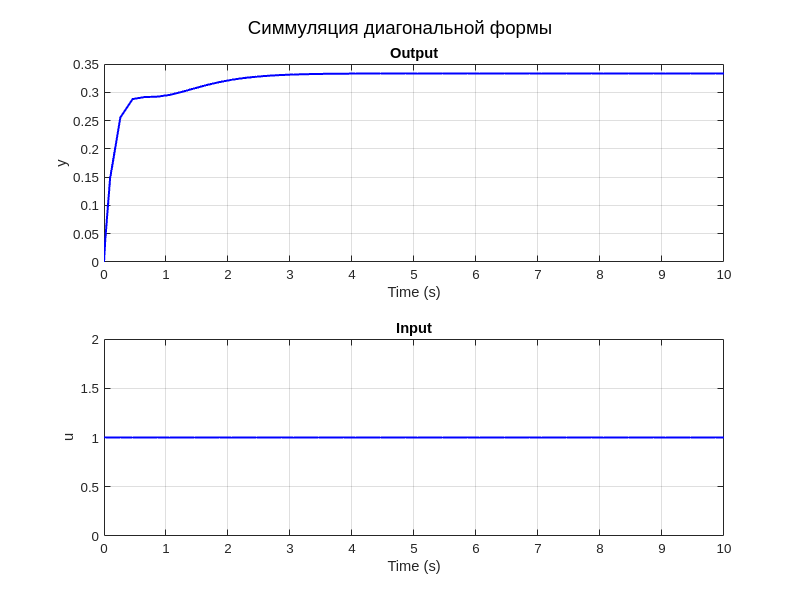

res = get(out4, "yout");
y = res{1};
u = res{2};
t = out4.tout;

figure('Position', [0 0 800 600]);

subplot(2, 1, 1); 
plot(t, y.Values.Data, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('y');
title('Output');
grid on;

subplot(2, 1, 2); 
plot(t, u.Values.Data, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('u');
title('Input');
grid on;

sgtitle("Симмуляция диагональной формы")

mdl = "task2_tf";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out5 = sim(simIn);

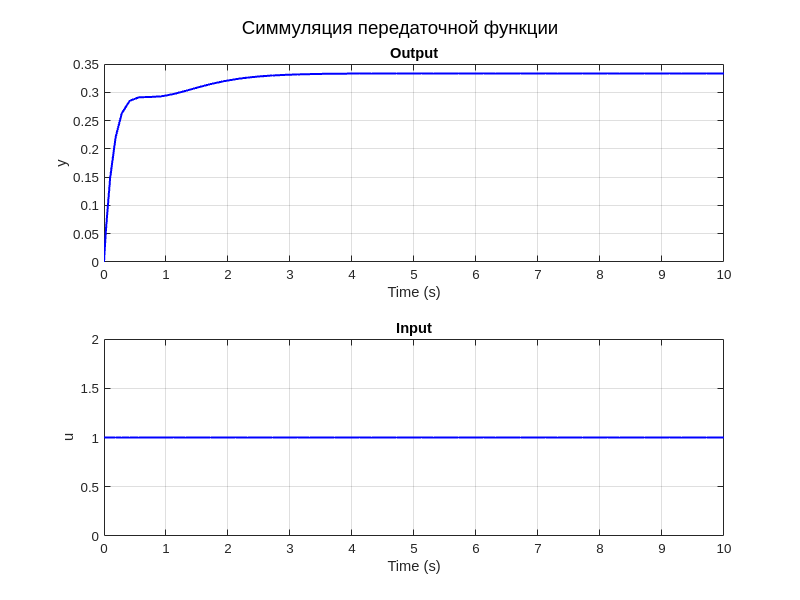

res = get(out5, "yout");
y = res{1};
u = res{2};
t = out5.tout;

figure('Position', [0 0 800 600]);

subplot(2, 1, 1); 
plot(t, y.Values.Data, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('y');
title('Output');
grid on;

subplot(2, 1, 2); 
plot(t, u.Values.Data, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('u');
title('Input');
grid on;

sgtitle("Симмуляция передаточной функции")

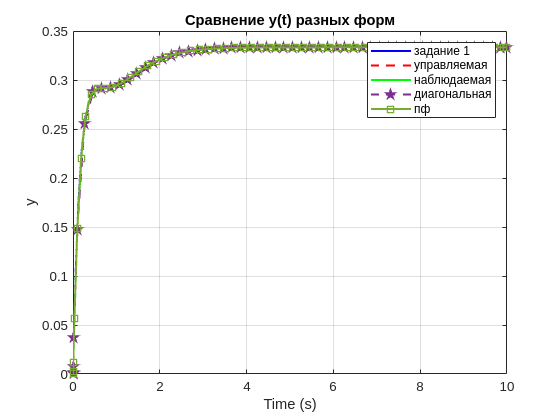

res = get(out1, "yout");
y1 = res{1};
t1 = out1.tout;

res = get(out2, "yout");
y2 = res{1};
t2 = out2.tout;

res = get(out3, "yout");
y3 = res{1};
t3 = out3.tout;

res = get(out4, "yout");
y4 = res{1};
t4 = out4.tout;

res = get(out5, "yout");
y5 = res{1};
t5 = out5.tout;

figure;

plot(t1, y1.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
plot(t2, y2.Values.Data, 'r--', 'LineWidth', 1.5);
plot(t3, y3.Values.Data, 'g-', 'LineWidth', 1.5);
plot(t4, y4.Values.Data, 'p--', 'LineWidth', 1.5);
plot(t5, y5.Values.Data, 's-', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Сравнение y(t) разных форм');
grid on;
legend('задание 1', 'управляемая', 'наблюдаемая', 'диагональная', 'пф');

## `Задание 3.Многоканальная система в форме вход-выход`

mdl = "task3";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out30 = sim(simIn);

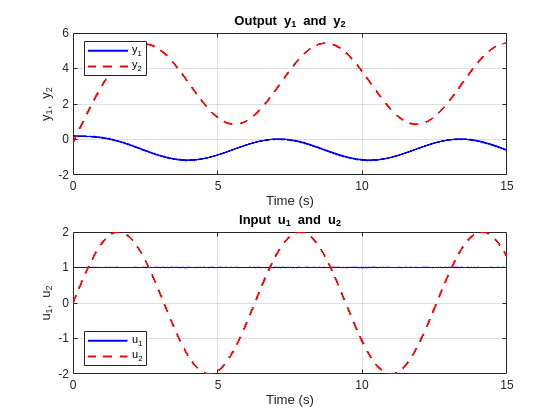

res = get(out30, "yout");
y1 = res{1};
y2 = res{2};
u1 = res{3};
u2 = res{4};

% Получение времени симуляции
t = out30.tout;

% Построение графика с двумя сабплотами
figure;

% Первый сабплот: y1 и y2
subplot(2, 1, 1); 
plot(t, y1.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
plot(t, y2.Values.Data, 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('y_1, y_2');
title('Output y_1 and y_2');
legend('y_1', 'y_2', 'Location', 'northwest');
hold off;

% Третий сабплот: u1 и u2
subplot(2, 1, 2); 
plot(t, u1.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
plot(t, u2.Values.Data, 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('u_1, u_2');
title('Input u_1 and u_2');
legend('u_1', 'u_2', 'Location', 'southwest');
hold off;

## `Задание 4. Многоканальная система в форме вход-состояние-выход`

mdl = "task4";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out40 = sim(simIn);

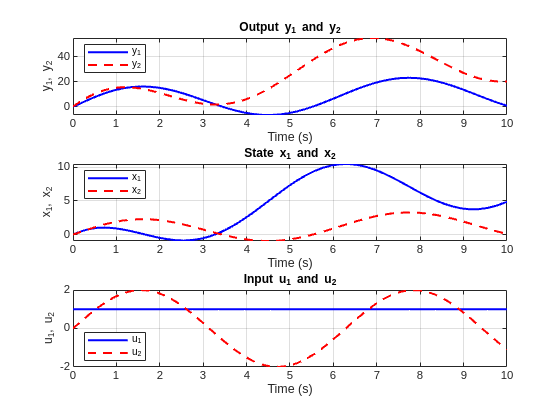

res = get(out40, "yout");
y1 = res{1};
y2 = res{2};
x1 = res{3};
x2 = res{4};
u1 = res{5};
u2 = res{6};

% Получение времени симуляции
t = out40.tout;

% Построение графика с двумя сабплотами
figure;

% Первый сабплот: y1 и y2
subplot(3, 1, 1); 
plot(t, y1.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
plot(t, y2.Values.Data, 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('y_1, y_2');
title('Output y_1 and y_2');
legend('y_1', 'y_2', 'Location', 'northwest');
hold off;

% Второй сабплот: x1 и x2
subplot(3, 1, 2); 
plot(t, x1.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
plot(t, x2.Values.Data, 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('x_1, x_2');
title('State x_1 and x_2');
legend('x_1', 'x_2', 'Location', 'northwest');
hold off;

% Третий сабплот: u1 и u2
subplot(3, 1, 3); 
plot(t, u1.Values.Data, 'b-', 'LineWidth', 1.5); hold on;
plot(t, u2.Values.Data, 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('u_1, u_2');
title('Input u_1 and u_2');
legend('u_1', 'u_2', 'Location', 'southwest');
hold off;